# Neural Network Pose Data

close all
data = load('pose.mat'); 
pose = data.pose; 
[d1,d2,npose,nsubj] = size(pose); 

% first 10 poses for each subject are training, the last three are test
ntr = 10; %# of training poses per subject
ntst = npose - ntr; % # of test poses per subject
Xtrain = zeros(d1,d2,1,nsubj*ntr); 
for jsubj = 1 : nsubj 
    jstart = (jsubj - 1)*ntr; 
    for jpos = 1:ntr 
        Xtrain(:,:,1,jstart+jpos)=pose(:,:,jpos,jsubj); 
    end
end

Label_train = categorical((kron(1:nsubj,ones(1,ntr)))'); 

%test set 
Xtest = zeros(d1,d2,1,nsubj*ntst); 
 for jsubj = 1:nsubj
     jstart = (jsubj -1)*ntst; 
    for jpos = 1:ntst 
        Xtest(:,:,1,jstart+jpos)=pose(:,:,ntr+jpos,jsubj); 
    end
end
    
Label_test = categorical((kron(1:nsubj,ones(1,ntst)))'); 

## Training Neural Network 

% Matlab - trainNetwork code

% worst accuracy - 0 - only 1 layer for 3
% layers = [ ...
%     imageInputLayer([d1,d2,1])
%     convolution2dLayer(5,20)
%     reluLayer
%     maxPooling2dLayer(2,'Stride',2)
%     fullyConnectedLayer(nsubj)
%     softmaxLayer
%     classificationLayer]; 


% accuracy 64.22% with 3,16 at 100 epochs
% 67.65% accuracy with 5,16 at 100 epochs
% 66.18% with 5,16 at 200 epochs
% 64.22% with 5,12 at 100 epochs
% 65.20% accuracy with 3,15 at 100 epochs
% 62.25% accuracy with 5,20 at 100 epochs


% 
% layers = [ ...
%     imageInputLayer([d1,d2,1])
%     convolution2dLayer(5,16,'Padding',1)
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2,'Stride',2)
%     convolution2dLayer(3,32,'Padding',1)
%     batchNormalizationLayer
%     reluLayer
%     maxPooling2dLayer(2,'Stride',2)
%     fullyConnectedLayer(nsubj)
%     softmaxLayer
%     classificationLayer];

% 69.61% adding groupedConvolution2dLayer
% 68.63 adding maxpooling layer 
% 67.16 accuracy adding convolution 2dLayer
% reduced to 61.76% when added maxPooling2dLayer
% %65.2% accuracy with this layer using 5,16
% %63.73% accuracy with this layer using 6,16
% AlexNet
layers = [...    
    imageInputLayer([d1,d2,1]) 
    convolution2dLayer(5,16,'Padding',1)     
    reluLayer 
    batchNormalizationLayer
    maxPooling2dLayer(2,'Stride',2) 
    groupedConvolution2dLayer(3,24,2,'Padding', 'same')      
    reluLayer
    batchNormalizationLayer
%     maxPooling2dLayer(2,'Stride',2)
%     convolution2dLayer(3,32,'Padding',1)
    reluLayer
    groupedConvolution2dLayer(3,26,2,'Padding','same')
    reluLayer
%     groupedConvolution2dLayer(3,26,2,'Padding','same') 
%     reluLayer
%     maxPooling2dLayer(2,'Stride',2)
%     fullyConnectedLayer(512)
%     reluLayer
%     dropoutLayer(0.5)
  fullyConnectedLayer(512)
  reluLayer
  dropoutLayer(0.5)
  fullyConnectedLayer(nsubj)
  softmaxLayer
  classificationLayer]; 

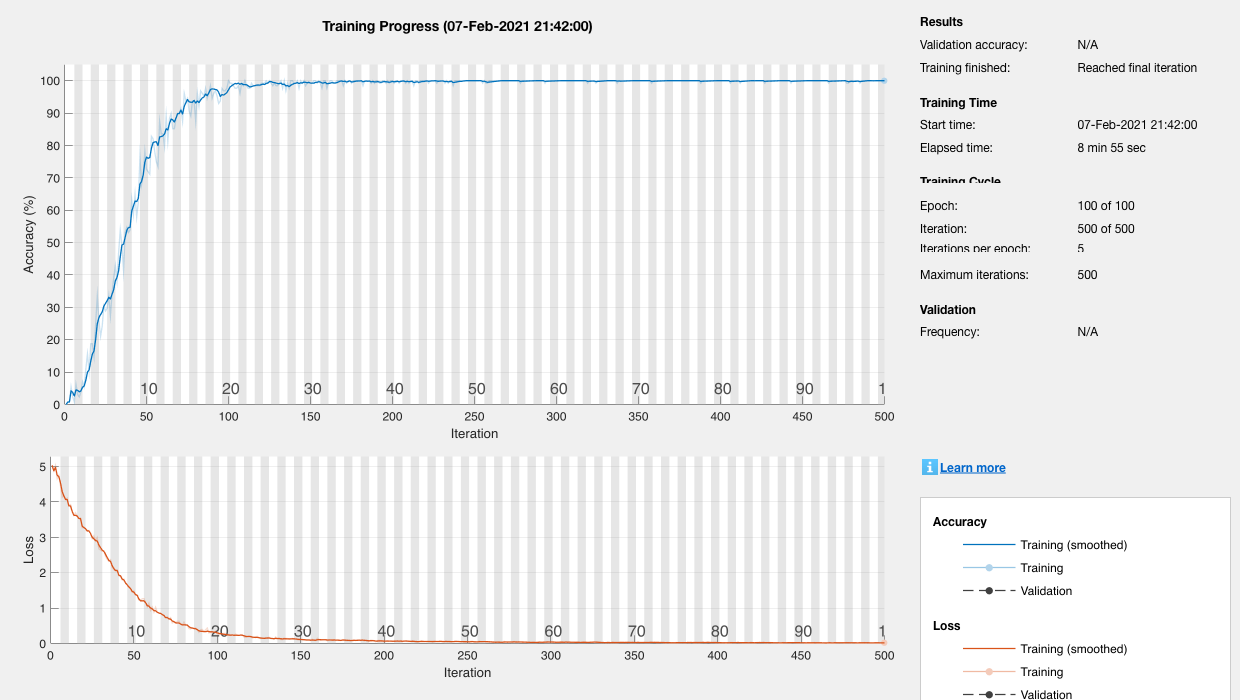

options = trainingOptions('sgdm',...
    'MaxEpochs',100,...
    'InitialLearnRate',1e-3,...
    'Verbose',false,...
    'Plots','training-progress'); 

net = trainNetwork(Xtrain,Label_train,layers,options); 

Label_test_predicted = classify(net,Xtest);
accuracy = sum(Label_test_predicted == Label_test)/numel(Label_test)

accuracy = 0.6765